## Problem 1

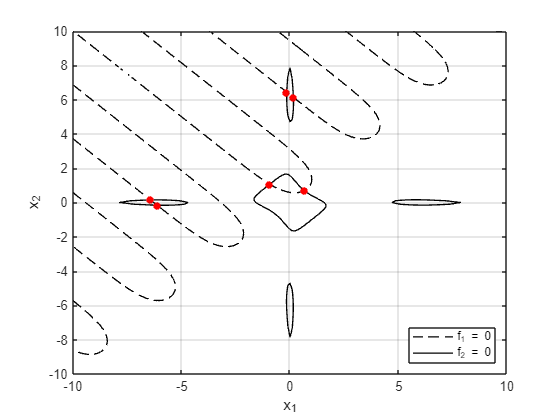

clear;clc;close all;
[x1, x2] = meshgrid(-10:0.1:10, -10:0.1:10);

f1_vals = zeros(size(x1));
f2_vals = zeros(size(x1));

for i = 1:numel(x1)
    F = nesfunc.system_equations1([x1(i); x2(i)]);
    f1_vals(i) = F(1);
    f2_vals(i) = F(2);
end

figure;
contour(x1, x2, f1_vals, [0 0], 'LineStyle','--','EdgeColor','black','LineWidth',1);
hold on;
contour(x1, x2, f2_vals, [0 0], 'LineStyle','-','EdgeColor','black','LineWidth',1); 

% Plot solutions from the table
solutions = [-6.437160, 0.155348;
             -0.932122, 1.067870;
             -0.155283, 6.439840;
             0.163333, 6.122430;
             0.667121, 0.690103;
             -6.117110, -0.163476];

plot(solutions(:,1), solutions(:,2), 'o', 'MarkerSize', 5, 'MarkerEdgeColor', 'red','MarkerFaceColor','r');

xlabel('x_1');
ylabel('x_2');
legend('f_1 = 0', 'f_2 = 0','Location','southeast');
grid on;
hold off;

## Problem 2

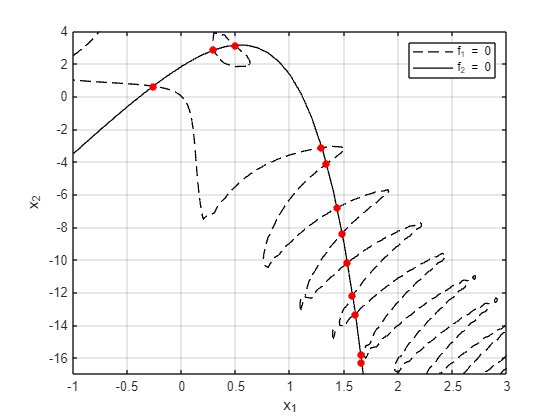

clear;clc;close all;
[x1, x2] = meshgrid(-1:0.1:3, -17:0.1:4);

f1_vals = zeros(size(x1));
f2_vals = zeros(size(x1));

for i = 1:numel(x1)
    F = nesfunc.system_equations2([x1(i); x2(i)]);
    f1_vals(i) = F(1);
    f2_vals(i) = F(2);
end

figure;
contour(x1, x2, f1_vals, [0 0], 'LineStyle','--','EdgeColor','black','LineWidth',1);
hold on;
contour(x1, x2, f2_vals, [0 0], 'LineStyle','-','EdgeColor','black','LineWidth',1); 

% Plot solutions from the updated table
solutions = [-0.260599, 0.622531;
             1.530510, -10.202200;
             1.663420, -16.282800;
             1.654580, -15.819200;
             1.433950, -6.820760;
             1.578220, -12.176700;
             1.337430, -4.140440;
             0.500000, 3.141590;
             0.299449, 2.836930;
             1.604570, -13.362900;
             1.294360, -3.137220;
             1.481320, -8.383610];

plot(solutions(:,1), solutions(:,2), 'o', 'MarkerSize', 5, 'MarkerEdgeColor', 'red','MarkerFaceColor','r');

xlabel('x_1');
ylabel('x_2');
legend('f_1 = 0', 'f_2 = 0','Location','northeast');
grid on;
hold off;

## Problem 3

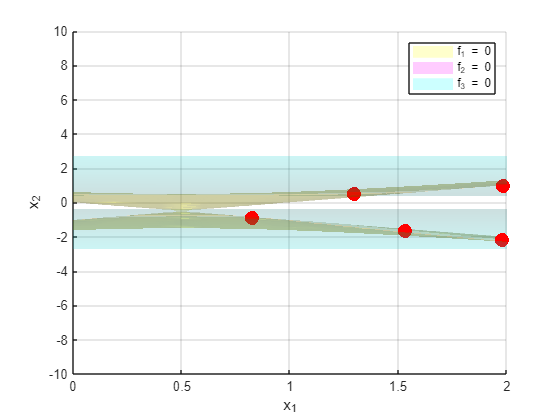

clear;clc;close all;

% Step 2: Generate a 3D grid of points
[x1, x2, x3] = meshgrid(0:0.1:2, -10:0.1:10, -1:0.1:1);

% Step 3: Evaluate the functions over the 3D grid
f1_vals = zeros(size(x1));
f2_vals = zeros(size(x1));
f3_vals = zeros(size(x1));

for i = 1:numel(x1)
    F = nesfunc.system_equations3([x1(i); x2(i); x3(i)]);
    f1_vals(i) = F(1);
    f2_vals(i) = F(2);
    f3_vals(i) = F(3);
end

% Step 4: Create 3D isosurface plots
figure;

% Plot isosurface for f1 = 0
iso1 = isosurface(x1, x2, x3, f1_vals, 0);
patch(iso1, 'FaceColor', 'yellow', 'EdgeColor', 'none', 'FaceAlpha', 0.2); % Red color for f1 = 0

% Adjust properties for isosurface 1
camlight('headlight'); % Adjust lighting for better visibility
lighting gouraud; % Use Gouraud lighting for smoother appearance
grid on; % Add grid lines for depth perception

hold on;

% Plot isosurface for f2 = 0
iso2 = isosurface(x1, x2, x3, f2_vals, 0);
patch(iso2, 'FaceColor', 'magenta', 'EdgeColor', 'none', 'FaceAlpha', 0.2); % Red color for f2 = 0

% Adjust properties for isosurface 2
camlight('headlight'); % Adjust lighting for better visibility
lighting gouraud; % Use Gouraud lighting for smoother appearance
grid on; % Add grid lines for depth perception

% Plot isosurface for f3 = 0
iso3 = isosurface(x1, x2, x3, f3_vals, 0);
patch(iso3, 'FaceColor', 'cyan', 'EdgeColor', 'none', 'FaceAlpha', 0.2); % Red color for f3 = 0

% Plot solutions from the table
solutions = [0.825297, -0.859034, -0.151946;
             1.299490, 0.525835, -0.642769;
             1.533662, -1.648068, 0.499604;
             1.981360, -2.172180, 0.775731;
             1.983283, 0.983378, -0.016762];

hold on;
scatter3(solutions(:,1), solutions(:,2), solutions(:,3), 100, 'k', 'filled','MarkerEdgeColor','red','MarkerFaceColor','red');

% Adjust properties for isosurface 3
camlight('headlight'); % Adjust lighting for better visibility
lighting gouraud; % Use Gouraud lighting for smoother appearance
grid on; % Add grid lines for depth perception

% Customize plot
xlabel('x_1');
ylabel('x_2');
zlabel('x_3');
legend('f_1 = 0', 'f_2 = 0', 'f_3 = 0', 'Location', 'northeast');
grid on;
hold off;

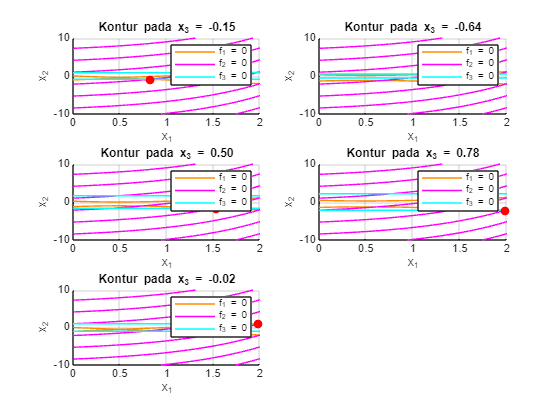

clear; clc; close all;

% Define the solutions
solutions = [0.825297, -0.859034, -0.151946;
             1.299490, 0.525835, -0.642769;
             1.533662, -1.648068, 0.499604;
             1.981360, -2.172180, 0.775731;
             1.983283, 0.983378, -0.016762];

% Step 2: Generate a 2D grid of points
[x1, x2] = meshgrid(0:0.1:2, -10:0.1:10);

figure;

% Loop through each solution to create contour plots
for k = 1:size(solutions, 1)
    z_const = solutions(k, 3);

    % Evaluate the functions over the 2D grid at the constant z value
    f1_vals = zeros(size(x1));
    f2_vals = zeros(size(x1));
    f3_vals = zeros(size(x1));

    for i = 1:numel(x1)
        F = nesfunc.system_equations3([x1(i); x2(i); z_const]);
        f1_vals(i) = F(1);
        f2_vals(i) = F(2);
        f3_vals(i) = F(3);
    end

    % Create a new subplot for each solution
    subplot(ceil(size(solutions, 1) / 2), 2, k);
    hold on;

    % Plot contours for f1, f2, and f3
    contour(x1, x2, f1_vals, [0 0], 'LineColor', '#FF8C00');
    contour(x1, x2, f2_vals, [0 0], 'LineColor', 'magenta');
    contour(x1, x2, f3_vals, [0 0], 'LineColor', 'cyan');

    % Mark the solution point on the contour plot
    plot(solutions(k, 1), solutions(k, 2), 'ko', 'MarkerEdgeColor', 'red', 'MarkerFaceColor', 'red');

    % Customize plot
    xlabel('x_1');
    ylabel('x_2');
    title(sprintf('Kontur pada x_3 = %.2f', z_const));
    legend({'f_1 = 0', 'f_2 = 0', 'f_3 = 0'}, 'Location', 'northeast');
    grid on;
    hold off;
end


% sgtitle('Plot Kontur 2D pada nilai x_3 berbeda');
